Discriminant function:


$$g_i(x) = x^tW_ix + w_i^tx + w_{i0}$$



$$W_i= -\frac{1}{2}{\Sigma}_i^{-1}$$



$$\mathbf{w}_i= \Sigma_i^{-1}\mu_i$$



$$w_{i0} = -\frac{1}{2}\mu_i^t\Sigma_i^{-1}\mu_i - \frac{1}{2}\ln|\Sigma_i|+ \ln P(w_i)$$


Since prior probabilities are equal, $P(w_i) = \frac{1}3}$

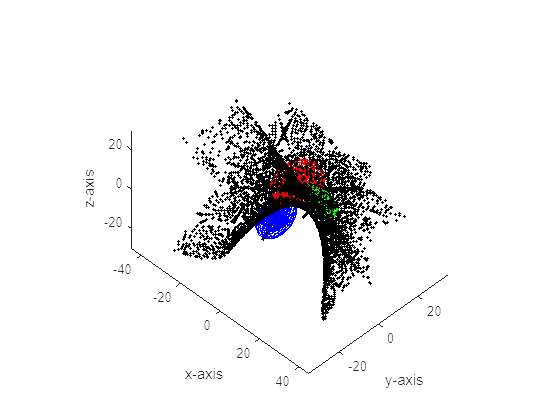

sigmaA = [6.5000 2.1651 1.2500; 2.1651 5.1250 2.3816; 1.2500 2.3816 2.3750];
sigmaB = [3.0814 0.4331 -1.4481;0.4331 0.94336 -0.6456;-1.4481 -0.6456 1.2880];
sigmaC = [6.8928 -1.3750 3.1945;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];

muA = [0; 4; 7];
muB = [10; 5; 5];
muC = [-2; -5; -5];

p = 1/3;

% (Num^3)-by-3 matrix containing the coordinates for regularily spaced
% points inside of a rectangular volume
x = vol3D([-30 30 -30 30 -30 30],200);

% create discriminant function
% gA = (x.')*cap_wA*x + (wA.')*x + wA_const;
gA = Discriminant(x, muA, sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% create 3 classes of dataset 
yA_correct = Gaussian_correct(3,1000, muA, sigmaA);
yB_correct = Gaussian_correct(3,1000, muB, sigmaB);
yC_correct = Gaussian_correct(3,1000, muC, sigmaC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Changes of mean move the centre of the dataset, so changes mean moves or shifts deicision boudaries. Covariances cnotrol the shape (spread) of the dataset, so if convariances change then decision boudaries will change shape decision boudaries. Decision boudaries become linear if covariances are the same.

Plot the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.

Case 1: Change sigma for class C same as sigma for class B, then the decision boundaries become parallel (linearly seprated) between class B and C 

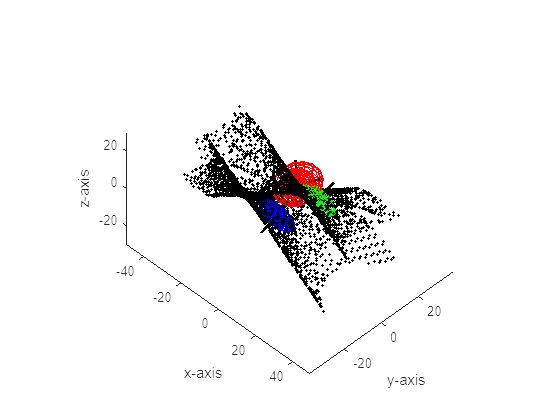

% case 1
% change of sigma for class C
sigmaC = [3.0814 0.4331 -1.4481;0.4331 0.94336 -0.6456;-1.4481 -0.6456 1.2880];

% create discriminant function
gA = Discriminant(x, muA, sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% create 3 classes of dataset 
yA_correct = Gaussian_correct(3,1000, muA, sigmaA);
yB_correct = Gaussian_correct(3,1000, muB, sigmaB);
yC_correct = Gaussian_correct(3,1000, muC, sigmaC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Case 2: Based on case 1, we further change mean of B and C so that they move away from orginal position.

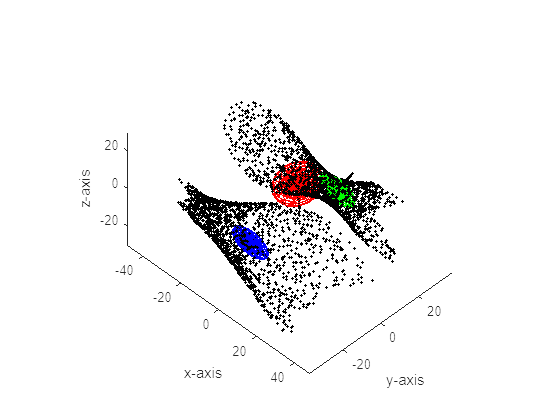

% case 2 
% change of mu for class B and C
muC = [-6; -15; -15];
muB = [15; 10; 10];

% create discriminant function
gA = Discriminant(x, muA, sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% create 3 classes of dataset 
yA_correct = Gaussian_correct(3,1000, muA, sigmaA);
yB_correct = Gaussian_correct(3,1000, muB, sigmaB);
yC_correct = Gaussian_correct(3,1000, muC, sigmaC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Plot changes of posterior probabilites. 

Case 1: $P(w_1) = 0.99999$, $ P(w_2) = 0.000005$ and $P(w_3) = 0.000005$

Case 2: $P(w_1) = 0.000005$, $P(w_3) = 0.99999$ and $P(w_3) = 0.000005$ 

Case 3: $P(w_3) = 0.000005$, $P(w_3) = 0.000005$ and $P(w_3) = 0.99999$

Through these cases, we can observe when priror probability of one class increases, the decision boudary moves away from the ellipsoid and getting closer to other classes. When priror probability of one class decreases, the decision boudary moves away to the ellipsoid of that class. To observe obvious differences, we need to assign extreme values for prior probabilites and classes that are more separated show less obvious due to order of magnituede.

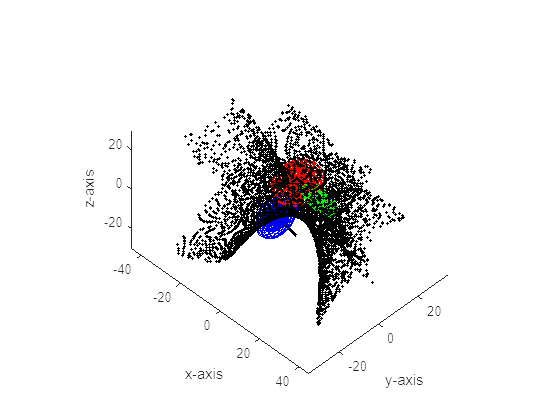

% reset means and covariances
sigmaC = [6.8928 -1.3750 3.1945;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
muB = [10; 5; 5];
muC = [-2; -5; -5];

% case 1
pA = 0.99999;
pB = 0.000005;
pC = 0.000005;
gA1 = Discriminant(x, muA, sigmaA, pA);
gB1 = Discriminant(x, muB, sigmaB, pB);
gC1 = Discriminant(x, muC, sigmaC, pC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A1 = find(abs(gA1 - max(gB1,gC1)) < espil);
index_B1 = find(abs(gB1 - max(gA1,gC1)) < espil);
index_C1 = find(abs(gC1 - max(gA1,gB1)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A1, index_B1, index_C1)

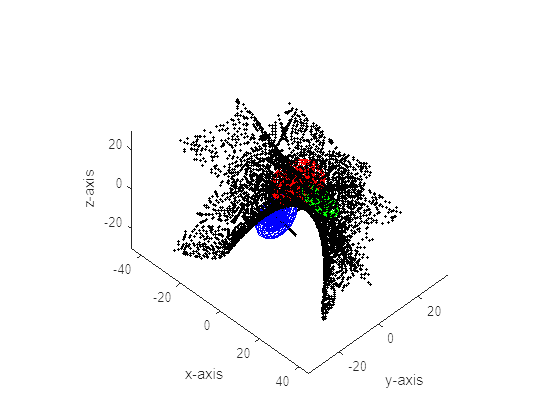

% case 2
pA = 0.000005;
pB = 0.99999;
pC = 0.000005;
gA2 = Discriminant(x, muA, sigmaA, pA);
gB2 = Discriminant(x, muB, sigmaB, pB);
gC2 = Discriminant(x, muC, sigmaC, pC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A2 = find(abs(gA2 - max(gB2,gC2)) < espil);
index_B2 = find(abs(gB2 - max(gA2,gC2)) < espil);
index_C2 = find(abs(gC2 - max(gA2,gB2)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A2, index_B2, index_C2)

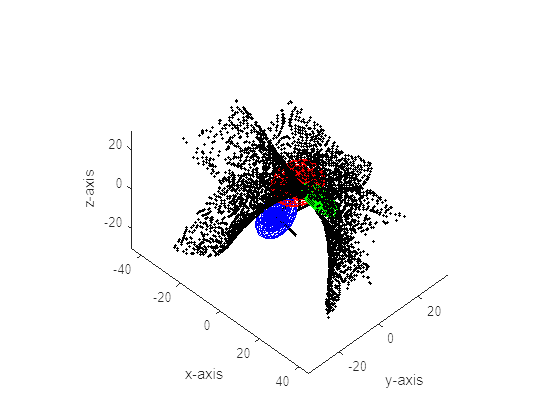

% case 3
pA = 0.000005;
pB = 0.000005;
pC = 0.99999;
gA3 = Discriminant(x, muA, sigmaA, pA);
gB3 = Discriminant(x, muB, sigmaB, pB);
gC3 = Discriminant(x, muC, sigmaC, pC);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A3 = find(abs(gA3 - max(gB3,gC3)) < espil);
index_B3 = find(abs(gB3 - max(gA3,gC3)) < espil);
index_C3 = find(abs(gC3 - max(gA3,gB3)) < espil);

% plot elliposid of class A, B, C
plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC);

length = 10;
plot_principal_axes(yA_correct,muA',length);
plot_principal_axes(yB_correct,muB',length);
plot_principal_axes(yC_correct,muC',length);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A3, index_B3, index_C3)

Risks:

For case 1, we can see from the plot that the two boundaries perfectly overlap. This is because using the 0-1 risk, the risk boundary is essentially the Baysien boundary.

For case 2, we increased lambda_AB (therefore so is lambda_BA), that is the risk of misclassify A and B is higher. As a result, classifying to C will be more likely than before, this results in a larger volume for C, as shown in the red boundary comparing to the black boundary.

For case 3, similarly,  we increased lambda_AC and this results in a larger volume for B, as shown in the red boundary comparing to the black boundary.

For case 4, similarly, we increased lambda_BC and this results in a larger volume for A, as shown in the red boundary comparing to the black boundary.

Case 1: 0-1 risk

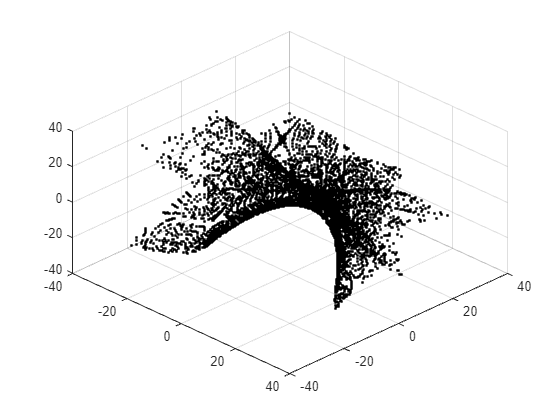


diff_A_index =

  1×0 empty double row vector


diff_B_index =

  1×0 empty double row vector


diff_C_index =

  1×0 empty double row vector



% create discriminant function
gA = Discriminant(x, muA, sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% For simplicity, lambda_AB = lambda_BA, lambda_AC = lambda_CA, etc
lambda_AB = 1; 
lambda_AC = 1;
lambda_BC = 1;
lambda_AA = 0;
lambda_BB = 0;
lambda_CC = 0;

gi_matrix = [gA;gB;gC];

[diff_A_index,diff_B_index,diff_C_index]=q5_plot(lambda_AA,lambda_BB,lambda_CC,lambda_AB,lambda_AC,lambda_BC,gi_matrix,x,index_A, index_B, index_C)

Using the 0-1 risk, the two boundaries are essentially the same, thus overlapping.

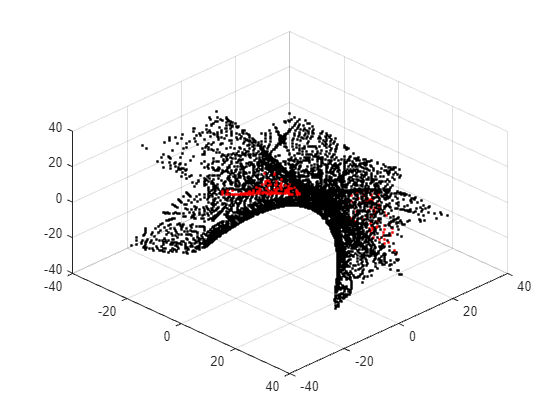

diff_A_index =    270   276   290   295   307   321   322   329   330   331   336   337   338   339   340   341   342   343   344   345   346   350   351   352   353   354   355   356   357   358   359   363   364   366   367   368   369   370   371   372   373   391   394   396   397   398   399   400   420   422


diff_B_index =    270   276   290   295   307   321   322   329   330   331   336   337   338   339   340   341   342   343   344   345   346   350   351   352   353   354   355   356   357   358   359   363   364   366   367   368   369   370   371   372   373   391   394   396   397   398   399   400   420   422



diff_C_index =

  1×0 empty double row vector



% case 2 increased lambda_AB
lambda_AB = 2; 
lambda_AC = 1;
lambda_BC = 1;
lambda_AA = 0;
lambda_BB = 0;
lambda_CC = 0;
[diff_A_index,diff_B_index,diff_C_index]=q5_plot(lambda_AA,lambda_BB,lambda_CC,lambda_AB,lambda_AC,lambda_BC,gi_matrix,x,index_A, index_B, index_C)

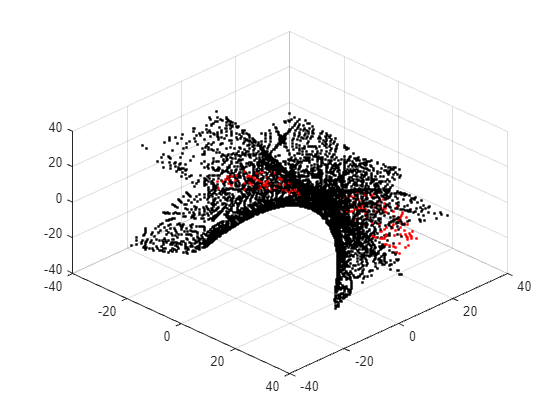

diff_A_index =          695         713         714         715         726         729         731         748         751         753         769         771         774         793         825         826         854         856         882         884         886         888         913         914         915         916         938         940         966         967         986         987         989         990         991         993        1010        1011        1012        1013        1015        1028        1029        1030        1034        1046        1047        1064        1068        1078



diff_B_index =

  1×0 empty double row vector



diff_C_index =          695         713         714         715         726         729         731         748         751         753         769         771         774         793         825         826         854         856         882         884         886         888         913         914         915         916         938         940         966         967         986         987         989         990         991         993        1010        1011        1012        1013        1015        1028        1029        1030        1034        1046        1047        1064        1068        1078


% case 3 increased lambda_AC
lambda_AB = 1; 
lambda_AC = 2;
lambda_BC = 1;
lambda_AA = 0;
lambda_BB = 0;
lambda_CC = 0;
[diff_A_index,diff_B_index,diff_C_index]=q5_plot(lambda_AA,lambda_BB,lambda_CC,lambda_AB,lambda_AC,lambda_BC,gi_matrix,x,index_A, index_B, index_C)

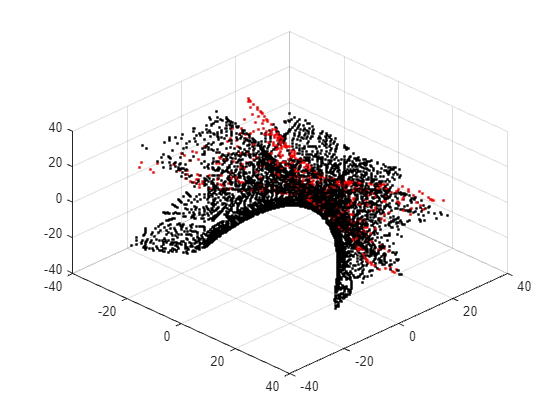


diff_A_index =

  1×0 empty double row vector



diff_B_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


diff_C_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% increased lambda_BC
lambda_AB = 1; 
lambda_AC = 1;
lambda_BC = 2;
lambda_AA = 0;
lambda_BB = 0;
lambda_CC = 0;
[diff_A_index,diff_B_index,diff_C_index]=q5_plot(lambda_AA,lambda_BB,lambda_CC,lambda_AB,lambda_AC,lambda_BC,gi_matrix,x,index_A, index_B, index_C)

Outliers

Through these 3 cases, we can observe that the boundaries are skewed towards to the outlier with increasing Mahalanobis distance. The nature of Bayes decision boundaries is sensative to outliers, because outliers have have large impacts to means and covariances measures which are sensative to outliers.

Case 1: Mahalanobis distance = 10

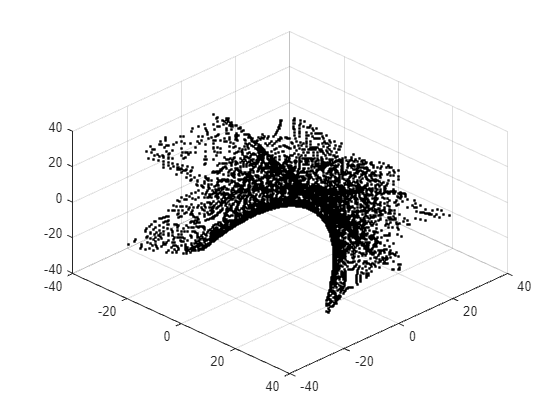

% outliers
% We do it on class A
distance = 10;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct;outlier_10'];
new_muA = mean(yA_outlier);
new_sigmaA = cov(yA_outlier);
% create discriminant function with new mu and new covariance
gA = Discriminant(x, new_muA', new_sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Case 2: Mahalanobis distance = 50

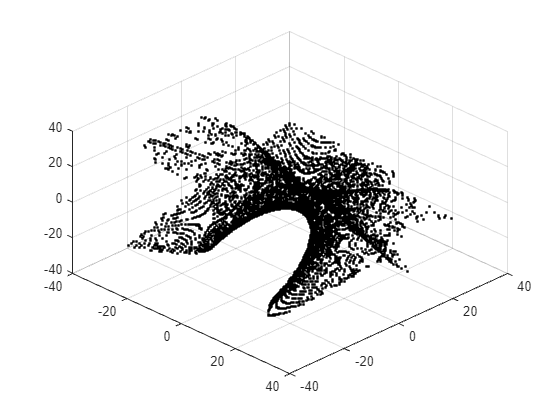

distance = 50;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct;outlier_10'];
new_muA = mean(yA_outlier);
new_sigmaA = cov(yA_outlier);
% create discriminant function with new mu and new covariance
gA = Discriminant(x, new_muA', new_sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Case 3: Mahalanobis distance = 100

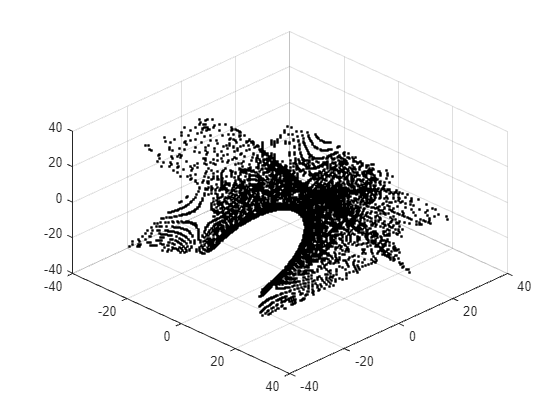

distance = 100;
inv_sigmaA = inv(sigmaA);
val = (distance^2)/inv_sigmaA(1,1);
val = sqrt(val);
outlier_10 = [val;4;7];
yA_outlier= [yA_correct;outlier_10'];
new_muA = mean(yA_outlier);
new_sigmaA = cov(yA_outlier);
% create discriminant function with new mu and new covariance
gA = Discriminant(x, new_muA', new_sigmaA, p);
gB = Discriminant(x, muB, sigmaB, p);
gC = Discriminant(x, muC, sigmaC, p);

% find index of results (decision boudaries in space of x)
espil = 0.1;
index_A = find(abs(gA - max(gB,gC)) < espil);
index_B = find(abs(gB - max(gA,gC)) < espil);
index_C = find(abs(gC - max(gA,gB)) < espil);

% plot decision boudaries
plot_decision_boundaries_three_classes(x, index_A, index_B, index_C)

Question 7

(a) Decision boundaries are not effective with a few data points within the dataset, beucase decision boudaries are sensative to outlier which have large impacts on means and covariances. With fewer data points, outliers have larger impacts on means and covariances and descision boundaries are more sensative and less effective.

(b) It is not appropriate to have decision boudaries that exihbit highly sensative to only a small number of data samples

(c) We can calculate Mahalanobis distance of each data point to observe if there are outliers 

(d) We can set up thresholds with certain values of Mahalanobis distance. If data points of Mahalanobis distance is higher than the thresholds, than we should treat them as outliers and remove them

Functions

function [diff_A_index,diff_B_index,diff_C_index] = q5_plot(lambda_AA,lambda_BB,lambda_CC,lambda_AB,lambda_AC,lambda_BC,gi_matrix,x,index_A, index_B, index_C) 
    cm1 = [lambda_AA lambda_AB lambda_AC];
    cm2 = [lambda_AB lambda_BB lambda_BC];
    cm3 = [lambda_AC lambda_BC lambda_CC];
    % calculate loss
    loss_gA = cm1*gi_matrix;
    loss_gB = cm2*gi_matrix;
    loss_gC = cm3*gi_matrix;

    % find index of results (decision boudaries in feature space of x)
    espil = 0.1;
    loss_index_A = find(abs(loss_gA - min(loss_gB,loss_gC)) < espil);
    loss_index_B = find(abs(loss_gB - min(loss_gA,loss_gC)) < espil);
    loss_index_C = find(abs(loss_gC - min(loss_gA,loss_gB)) < espil);

    % find index of differences between original and loss
    diff_A = setdiff(loss_index_A ,index_A);
    diff_A_index = find(ismember(loss_index_A,diff_A));

    diff_B = setdiff(loss_index_B, index_B);
    diff_B_index = find(ismember(loss_index_B,diff_B));

    diff_C = setdiff(loss_index_C, index_C);
    diff_C_index = find(ismember(loss_index_C,diff_C));

    % plot decision boudaries of loss
    scatter3(x(loss_index_A,1),x(loss_index_A,2),x(loss_index_A,3),'red.');
    hold on
    scatter3(x(loss_index_B,1),x(loss_index_B,2),x(loss_index_B,3),'red.');
    hold on
    scatter3(x(loss_index_C,1),x(loss_index_C,2),x(loss_index_C,3),'red.');
    hold on
    plot_decision_boundaries_three_classes(x, index_A, index_B, index_C);
    view(45,45);
    hold off
end

% function for discriminant analysis
function gi = Discriminant(x, mu, sigma, prob)
    % caluclate terms for discriminat function separatly
    inv_sigma = inv(sigma);
    cap_w = -1/2*inv_sigma;
    w = inv_sigma*mu;
    w_const = -1/2*(mu.')*inv_sigma*mu - 1/2*log(det(sigma)) + log(prob);
    
    % create discriminant function
    gi = dot((x*cap_w).',x.') + (w.')*x.' + w_const;
end

% function for accurate dataset
function x = Gaussian_correct(D,K, mu, sigma)
    data = randn(K,D);
    % singular decomposition of covariance
    [u,s,v] = svd(sigma);
    s = sqrt(s);
    % only use left or right singular vectors
    % use left here to create correlations
    data_correlated = data*s*u' + mu';
    m = mean(data_correlated); % mean of data generated with specified mean
    c = cov(data_correlated); %covarinace of data generated with specified covarinace

    % subtracting mean
    x = data_correlated - m;

    % Whitening transformation
    % Peform eigenvalue/eigenvector decomposition
    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    x = x * w * diag(1./sqrt(d_sorted));
    x = x*s*u' + mu';
end

function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%   
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;
end

% function to plot decision boudaries
function plot_decision_boundaries_three_classes(x, indexA, indexB, indexC)
    scatter3(x(indexA,1),x(indexA,2),x(indexA,3),'black.');
    hold on
    scatter3(x(indexB,1),x(indexB,2),x(indexB,3),'black.');
    hold on
    scatter3(x(indexC,1),x(indexC,2),x(indexC,3),'black.');
    view(45,45);
    hold off
end

% function to plot three classes ellipsoid
function plot_elliposid_three_classes(muA, sigmaA, muB, sigmaB, muC, sigmaC)
    % Plot the ellipsoid of the 3 classes
    n = 15;
    % Plot class A
    mu = muA';
    sigma = sigmaA;
    [U,S,V] = svd(sigma);
    S = sqrt(S);
    
    % Class A, 1x standard deviation
    [x1,y1,z1]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
    data_correlated1 = [x1(:), y1(:), z1(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data1=transform_ellipsoid(data_correlated1,n,mu,sqrt(S),U);
    x1 = reshape(data1(:, 1), size(x1));
    y1 = reshape(data1(:, 2), size(y1));
    z1 = reshape(data1(:, 3), size(z1));
        
    % Class A, 2x standard deviation
    [x2,y2,z2]=ellipsoid(0, 0, 0, 2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
    data_correlated2 = [x2(:), y2(:), z2(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data2=transform_ellipsoid(data_correlated2,n,mu,2*sqrt(S),U);
    x2 = reshape(data2(:, 1), size(x2));
    y2 = reshape(data2(:, 2), size(y2));
    z2 = reshape(data2(:, 3), size(z2));
        
    % Class A, 3x standard deviation
    [x3,y3,z3]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
    data_correlated3 = [x3(:), y3(:), z3(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data3 = transform_ellipsoid(data_correlated3,n,mu,3*sqrt(S),U);
    x3 = reshape(data3(:, 1), size(x3));
    y3 = reshape(data3(:, 2), size(y3));
    z3 = reshape(data3(:, 3), size(z3));
    
    
    % Plot class B
    mu = muB';
    sigma = sigmaB;
    [U,S,V] = svd(sigma);
    S = sqrt(S);
    
    % Class B, 1x standard deviation
    [x4,y4,z4]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
    data_correlated4 = [x4(:), y4(:), z4(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data4=transform_ellipsoid(data_correlated4,n,mu,sqrt(S),U);
    x4 = reshape(data4(:, 1), size(x4));
    y4 = reshape(data4(:, 2), size(y4));
    z4 = reshape(data4(:, 3), size(z4));
        
    % Class B, 2x standard deviation
    [x5,y5,z5]=ellipsoid(0, 0, 0,  2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
    data_correlated5 = [x5(:), y5(:), z5(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data5=transform_ellipsoid(data_correlated5,n,mu,2*sqrt(S),U);
    x5 = reshape(data5(:, 1), size(x5));
    y5 = reshape(data5(:, 2), size(y5));
    z5 = reshape(data5(:, 3), size(z5));
        
    % Class B, 3x standard deviation
    [x6,y6,z6]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
    data_correlated6 = [x6(:), y6(:), z6(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data6 = transform_ellipsoid(data_correlated6,n,mu,3*sqrt(S),U);
    x6 = reshape(data6(:, 1), size(x6));
    y6 = reshape(data6(:, 2), size(y6));
    z6 = reshape(data6(:, 3), size(z6));
    
    
    % Plot class C
    mu = muC';
    sigma = sigmaC;
    [U,S,V] = svd(sigma);
    S = sqrt(S);
    
    % Class C, 1x standard deviation
    [x7,y7,z7]=ellipsoid(0, 0, 0, sqrt(sigma(1,1)), sqrt(sigma(2,2)), sqrt(sigma(3,3)), n);
    data_correlated7 = [x7(:), y7(:), z7(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data7=transform_ellipsoid(data_correlated7,n,mu,sqrt(S),U);
    x7 = reshape(data7(:, 1), size(x7));
    y7 = reshape(data7(:, 2), size(y7));
    z7 = reshape(data7(:, 3), size(z7));
           
    % Class C, 2x standard deviation
    [x8,y8,z8]=ellipsoid(0, 0, 0, 2*sqrt(sigma(1,1)), 2*sqrt(sigma(2,2)), 2*sqrt(sigma(3,3)), n);
    data_correlated8 = [x8(:), y8(:), z8(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data8=transform_ellipsoid(data_correlated8,n,mu,2*sqrt(S),U);
        
    x8 = reshape(data8(:, 1), size(x8));
    y8 = reshape(data8(:, 2), size(y8));
    z8 = reshape(data8(:, 3), size(z8));
        
    % Class C, 3x standard deviation
    [x9,y9,z9]=ellipsoid(0, 0, 0, 3*sqrt(sigma(1,1)), 3*sqrt(sigma(2,2)), 3*sqrt(sigma(3,3)), n);
    data_correlated9 = [x9(:), y9(:), z9(:)]*S*U' + repmat(mu,(n+1)^2,1);
    data9 = transform_ellipsoid(data_correlated9,n,mu,3*sqrt(S),U);
    x9 = reshape(data9(:, 1), size(x9));
    y9 = reshape(data9(:, 2), size(y9));
    z9 = reshape(data9(:, 3), size(z9));
    
    
    figure
    hold on
    surf(x1,y1,z1,'EdgeColor','r');
    hold on
    surf(x2,y2,z2,'EdgeColor','r');
    hold on
    surf(x3,y3,z3,'EdgeColor','r');
    hold on
    surf(x4,y4,z4,'EdgeColor','g');
    hold on
    surf(x5,y5,z5,'EdgeColor','g');
    hold on
    surf(x6,y6,z6,'EdgeColor','g');
    hold on
    surf(x7,y7,z7,'EdgeColor','b');
    hold on
    surf(x8,y8,z8,'EdgeColor','b');
    hold on
    surf(x9,y9,z9,'EdgeColor','b');
    
    axis equal
    alpha 0
    xlabel('x-axis')
    ylabel('y-axis')
    zlabel('z-axis')
end

% withening transform axes 
function data = transform_ellipsoid(data_corr,n,mu,S,U)
    m = mean(data_corr); 
    c = cov(data_corr); 
    data_corr = data_corr -repmat(mu,(n+1)^2,1);

    [v,d] = eig(c);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );
    w = v(:, idx_sorted);
    data_corr = data_corr * w * diag(1./sqrt(d_sorted));
    data = data_corr*S*U' + repmat(mu,(n+1)^2,1);
end

% plot principla axes
function plot_principal_axes(y,mu,length)
    y_new = y - repmat(mu,1000,1);
    [U_new, S_new, V_new] = svd(y_new);
    line([mu(1), mu(1) + length*V_new(1, 1)], [mu(2), mu(2) + length*V_new(2, 1)], [mu(3), mu(3) + length*V_new(3, 1)], 'Color', 'black', 'LineWidth', 2);
    line([mu(1), mu(1) + length*V_new(1, 2)], [mu(2), mu(2) + length*V_new(2, 2)], [mu(3), mu(3) + length*V_new(3, 2)], 'Color', 'black', 'LineWidth', 2);
    line([mu(1), mu(1) + length*V_new(1, 3)], [mu(2), mu(2) + length*V_new(2, 3)], [mu(3), mu(3) + length*V_new(3, 3)], 'Color', 'black', 'LineWidth', 2);
end